# Documentation -- case of a horizontal line

clearvars;close all;clc;
load('exampleData.mat','u','t','nodes')
u = squeeze(u(:,1,:));
fs = 1./median(diff(t));
fprintf('Sampling frequency is %1.1f Hz \n',fs);

Sampling frequency is 9.0 Hz 


u0= u;
clear geometry
nodes.Z = nodes.Z(:,1);
nodes.Y = nodes.Y(1,:);
z = 50.*ones(size(nodes.Z(:,1)));
y = 75 + nodes.Y(1,:)';

rng(10)


## New grid

clf;close all;

N = numel(t);
u = reshape(u,N,[])';

newY = linspace(1,300,20);

fprintf('The new grid is %i by %i \n',[numel(z),1]);

The new grid is 3 by 1 


fprintf('The old grid is %i by %i \n',[size(newY,1),size(newY,2)]);

The old grid is 1 by 20 


% Remove nodes identical to the target nodes, if exist
newY = unique(newY);
%%
newZ = unique(z).*ones(size(newY));
Cuz = 7; % Decay coeficient for Davenport model
Cuy = 7; % Decay coeficient for Davenport model


Nyy = numel(newY);
Nzz = Nyy;  % single vertical mast

tic
[newU,uCheck, nodes2] = condWindSim2D(u,t,y,z,newY,newZ,Cuy,Cuz);
toc

Elapsed time is 6.616859 seconds.



newU = reshape(newU,[],Nyy);

## Plot time series

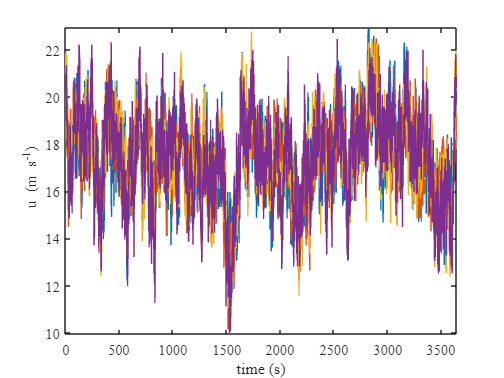

figure
plot(t,uCheck(:,1:5:16));
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')
set(gcf,'color','w')
xlabel('time')
axis tight
xlabel('time (s)')
ylabel(' u (m s^{-1})')

## Mean wind speed

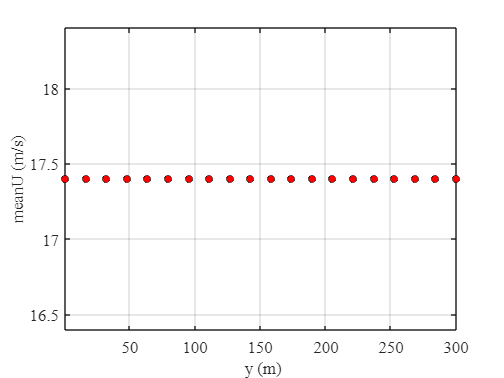


clf;close all;
figure
plot(nodes2.Y,reshape(mean(newU),[],1),'ko','markerfacecolor','r')
hold on
ylabel('meanU (m/s)')
xlabel(' y (m)')
axis tight
ylim([mean(u(:))-1,mean(u(:))+1])
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')
set(gcf,'color','w')
grid on

## Check the Turbulence intensity simulated inside the grid

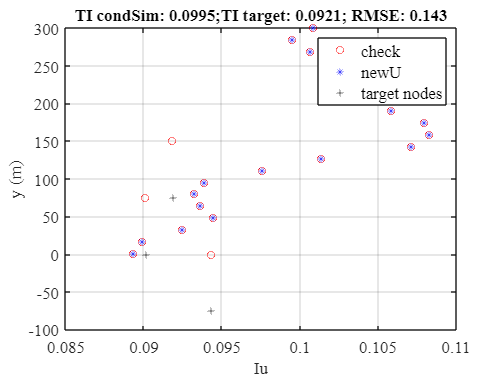


clf;close all;
figure
plot(std(uCheck)/mean(uCheck(:)),nodes2.Ycheck,'ro',...
    reshape(std(newU),[],Nzz)/mean(newU(:)),nodes2.Y,'b*',...
    std(reshape(u0,[],numel(z)))./mean(u0(:)),nodes.Y(:),'k+')
legend('check','newU','target nodes')

newSTD = interp1(nodes.Z,squeeze(std(u0)),newY,'nearest','extrap');
myRMSE = RMSE(std(newU),newSTD(:)');


title(['TI condSim: ',num2str(mean(reshape(std(newU),[],Nyy*1))./mean(u(:)),3),';TI target: ',...
    num2str(mean(std(reshape(u0,[],numel(z)))./mean(u(:))),3),'; RMSE: ',num2str(myRMSE,3)])
xlabel('Iu')
ylabel('y (m)')
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')
set(gcf,'color','w')
grid on

## RMSE between target and simulated wind velocity at the nodes

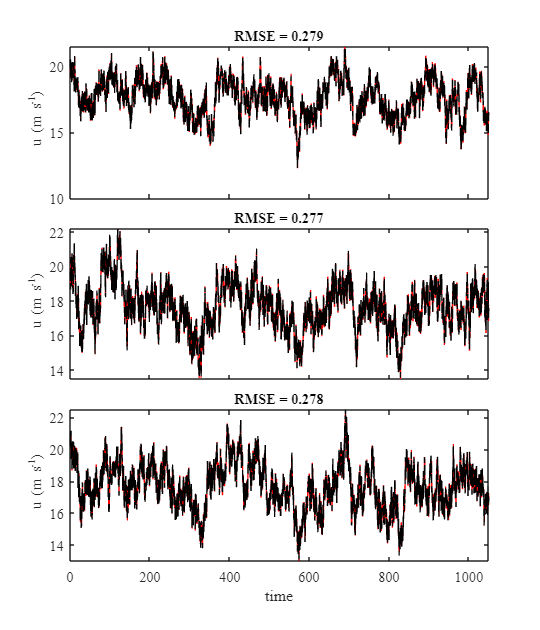


%  it should be near zero
clear ind2
clc
clf;close all

figure('position',[33    82   600   700])
tiledlayout(min(6,numel(y)),1,"TileSpacing","tight")
for jj=1:min(6,numel(y))
    nexttile
    [ind2] = find(nodes2.Ycheck(:)==y(jj) & nodes2.Zcheck(:)==z(jj));
    plot(t,uCheck(:,ind2),'r',t,u(jj,:),'k--');
    title(['RMSE = ',num2str(RMSE(uCheck(:,ind2),u(jj,:)),3)])
    xlim([0 1050])
    ylabel(' u (m s^{-1})')
    if jj<min(6,numel(y)),
        set(gca,'XTickLabel', []);
    end
end
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')
set(gcf,'color','w')
xlabel('time')

## Check the PSD at the target and simulated nodes

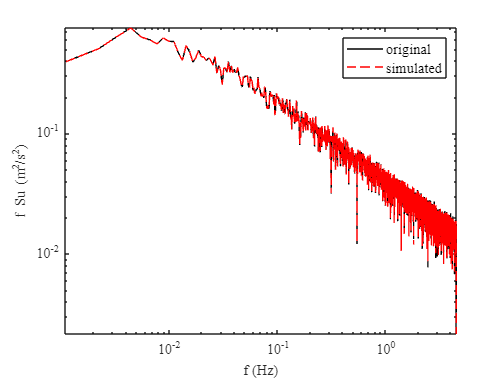


%  It should be identical
fs = 1/median(diff(t));
[ind2] = find(nodes2.Ycheck(:)==y(1) & nodes2.Zcheck(:)==z(1));

[Su0,f] = pwelch(detrend(u(1,:))',[],[],[],fs);
[Su1,f] = pwelch(detrend(uCheck(:,ind2))',[],[],[],fs);

figure
loglog(f,f.*Su0,'k',f,f.*Su1,'r--');
legend('original','simulated')
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')
set(gcf,'color','w')
xlabel('f (Hz)')
ylabel ('f Su (m^2/s^2)')
axis tight
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

set(gcf,'color','w')


## Coherence

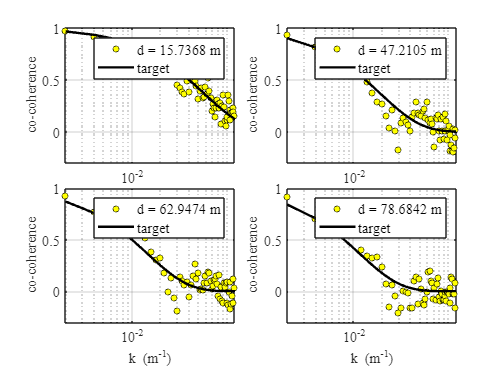


N = numel(t);
Nblock = 20; % a lot of block here to make it easier to visualize
Ncoh = round(N/Nblock);
if mod(Ncoh,2)
    cocoh = zeros(Nzz-1,round(Ncoh/2));
else
    cocoh = zeros(Nzz-1,round(Ncoh/2)+1);
end
% computation of the cocoherence using the function coherence
clear dy uCoh
ll=1;
y1 = nodes2.Y;
for ii=2:min(10,Nzz)
        [cocoh(ll,:),~,freq] = coherence(detrend(newU(:,2)),detrend(newU(:,ii)),Ncoh,round(Ncoh/2),Ncoh,fs);
        dz(ll) = abs(y1(ii)-y1(2));
        uCoh(ll) = 0.5* abs(mean(newU(:,2))+ mean(newU(:,ii)));
        ll=ll+1;
end

% matrix distance along y
distTarget = [20 40 60 80];

figure
tiledlayout(2,2,'TileSpacing','tight')
for ii=1:numel(distTarget)
    [~,indDist] = min(abs(dz-distTarget(ii)));
    k = 2*pi*freq./uCoh(indDist);
    nexttile
    semilogx(k,squeeze(cocoh(indDist,:)),'ko','markerfacecolor','y','markersize',5);
    box on;hold on
    plot(k,exp(-7.*dz(indDist).*freq/uCoh(indDist)),'k','linewidth',2);
    legend(['d = ',num2str(dz(indDist)),' m'],'target');
    xlim([0,0.12])
    ylim([-0.3,1])
    ylabel('co-coherence')
    if ii>2,        xlabel('k (m^{-1})');    end
    set(gcf,'color','w')
    grid on
end
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')